% image
imageFolder = 'imagemitsuba/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更
imgcnt = 1;
matFilePath = fullfile(imageFolder, imageFiles(imgcnt).name);
data = load(matFilePath);

% tonemapping
cform1 = makecform('xyl2xyz')

cform1 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


xyYImg = data.image_np_xyY; 
% Y-ReinhardTMO
LDR_Y = ReinhardTMO(xyYImg(:,:,3));
%xy
xyYImg(:,:,1) = 0.3127;
xyYImg(:,:,2) = 0.3290;
xyY_aft = cat(3,xyYImg(:,:,1),xyYImg(:,:,2),LDR_Y);
xyzImg = applycform(xyY_aft,cform1);

%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

linear_rgb = c.xyz_to_linear_rgb(xyzImg);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);

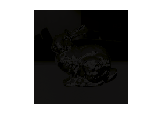


imshow(digital_rgb);

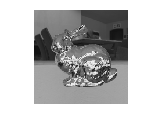


% confirm 
rgbImg = xyz2rgb(xyzImg);
imshow(rgbImg);